## Read data


datdir = '/Users/clinpsywoo/Dropbox/2011-yr/Teaching/R_stats/Stats2_2021Fall/data/study1/';

dat = importdata(fullfile(datdir, 'demographics_anova.csv'));


size(dat.textdata)

ans =     34    21


size(dat.data)

ans =     33    19


33 x 19 에서 33은 subject 명수, 19는 첫번째 열은 age, 2-10열까지 rating_low_down, rating_low_passive, rating_low_up, rating_med_down... 순서. 11-19열까지 nps_...

rating = dat.data(:,2:10);
nps = dat.data(:,11:19);
age = dat.data(:,1);

for i = 1:33 % subject
%     x{i} = [-1 -1 -1 0 0 0 1 1 1;-1 0 1 -1 0 1 -1 0 1]';
    x{i} = [1 1 1 2 2 2 3 3 3;1 2 3 1 2 3 1 2 3]';
    x{i}(:,3) = zscore(x{i}(:,1)).*zscore(x{i}(:,2));
    y_rating{i} = rating(i,:)';
    y_nps{i} = nps(i,:)';
end


## Multi-level GLM

x: heat intensity & regulation

y: ratings or nps

% run the multilevel GLM
stats = glmfit_multilevel(y_rating, x, age, 'names', {'int', 'heatlv', 'reg', 'interact'});

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  33, Predictors:   2
Outcome names: int	heatlv	reg	interact	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.00 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	int	heatlv	reg	interact	
Adj. mean	110.19	39.50	7.32	1.60	

2nd-level B01
	int	heatlv	reg	interact	
Coeff	110.19	39.50	7.32	1.60	
STE	14.65	8.40	9.62	4.79	
t	7.52	4.70	0.76	0.33	
Z	5.63	4.05	0.75	0.33	
p	0.00000	0.00005	0.45223	0.74096	


2nd-level B02
	int	heatlv	reg	interact	
Coeff	-0.72	0.03	0.18	-0.12	
STE	0.50	0.29	0.33	0.16	
t	-1.44	0.11	0.56	-0.76	
Z	-1.40	0.11	0.55	-0.75	
p	0.16075	0.91466	0.58101	0.45424	

________________________________________


% with weighted option
stats = glmfit_multilevel(y_rating, x, age, 'names', {'intercept', 'heat_level', 'regulation', 'interact'}, 'weighted');

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  33, Predictors:   2
Outcome names: intercept	heat_level	regulation	interact	
Weighting option: weighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	R & B - type Empirical Bayes reweighting.
Total time: 0.02 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	intercept	heat_level	regulation	interact	
Adj. mean	109.96	37.09	7.00	-0.33	

2nd-level B01
	intercept	heat_level	regulation	interact	
Coeff	109.96	37.09	7.00	-0.33	
STE	14.68	8.85	9.52	4.98	
t	7.49	4.19	0.74	-0.07	
Z	5.62	3.70	0.73	-0.07	
p	0.00000	0.00022	0.46784	0.94705	


2nd-level B02
	intercept	heat_level	regulation	interact	
Coeff	-0.71	0.06	0.20	-0.03	
STE	0.51	0.31	0.33	0.18	
t	-1.40	0.20	0.59	-0.17	
Z	-1.37	0.20	0.58	-0.16	
p	0.17059	0.84014	0.56045	0.86943	

________________________________________


% with weighted option + bootstrap option
stats = glmfit_multilevel(y_rating, x, age, 'names', {'intercept', 'heat_level', 'regulation', 'interact'}, 'weighted', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  33, Predictors:   2
Outcome names: intercept	heat_level	regulation	interact	
Weighting option: weighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	R & B - type Empirical Bayes reweighting.
 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.01 s, bias correct in 0.00 s 
Total time: 1.00 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intercept	heat_level	regulation	interact	
Adj. mean	108.10	-0.63	38.19	0.02	5.41	0.26	0.03	-0.05	

2nd-level B01
	intercept	heat_level	regulation	interact	
Coeff	109.96	37.09	7.00	-0.33	
STE	15.02	8.60	9.37	4.72	
t	7.49	4.19	0.74	-0.07	
Z	4.24	3.40	0.84	-0.15	
p	0.00002	0.00069	0.40315	0.87870	


2nd-level B02
	intercept	heat_level	regu

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  33, Predictors:   1
Outcome names: intercept	heat_level	regulation	interaction	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: Yes
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.00 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	intercept	heat_level	regulation	interaction	
Adj. mean	90.13	40.37	12.44	-1.86	

2nd-level B01
	intercept	heat_level	regulation	interaction	
Coeff	90.13	40.37	12.44	-1.86	
STE	4.50	2.50	2.87	1.44	
t	20.04	16.15	4.33	-1.30	
Z	8.21	8.21	3.81	-1.27	
p	0.00000	0.00000	0.00014	0.20409	

________________________________________
Warning! Unknown input string option.


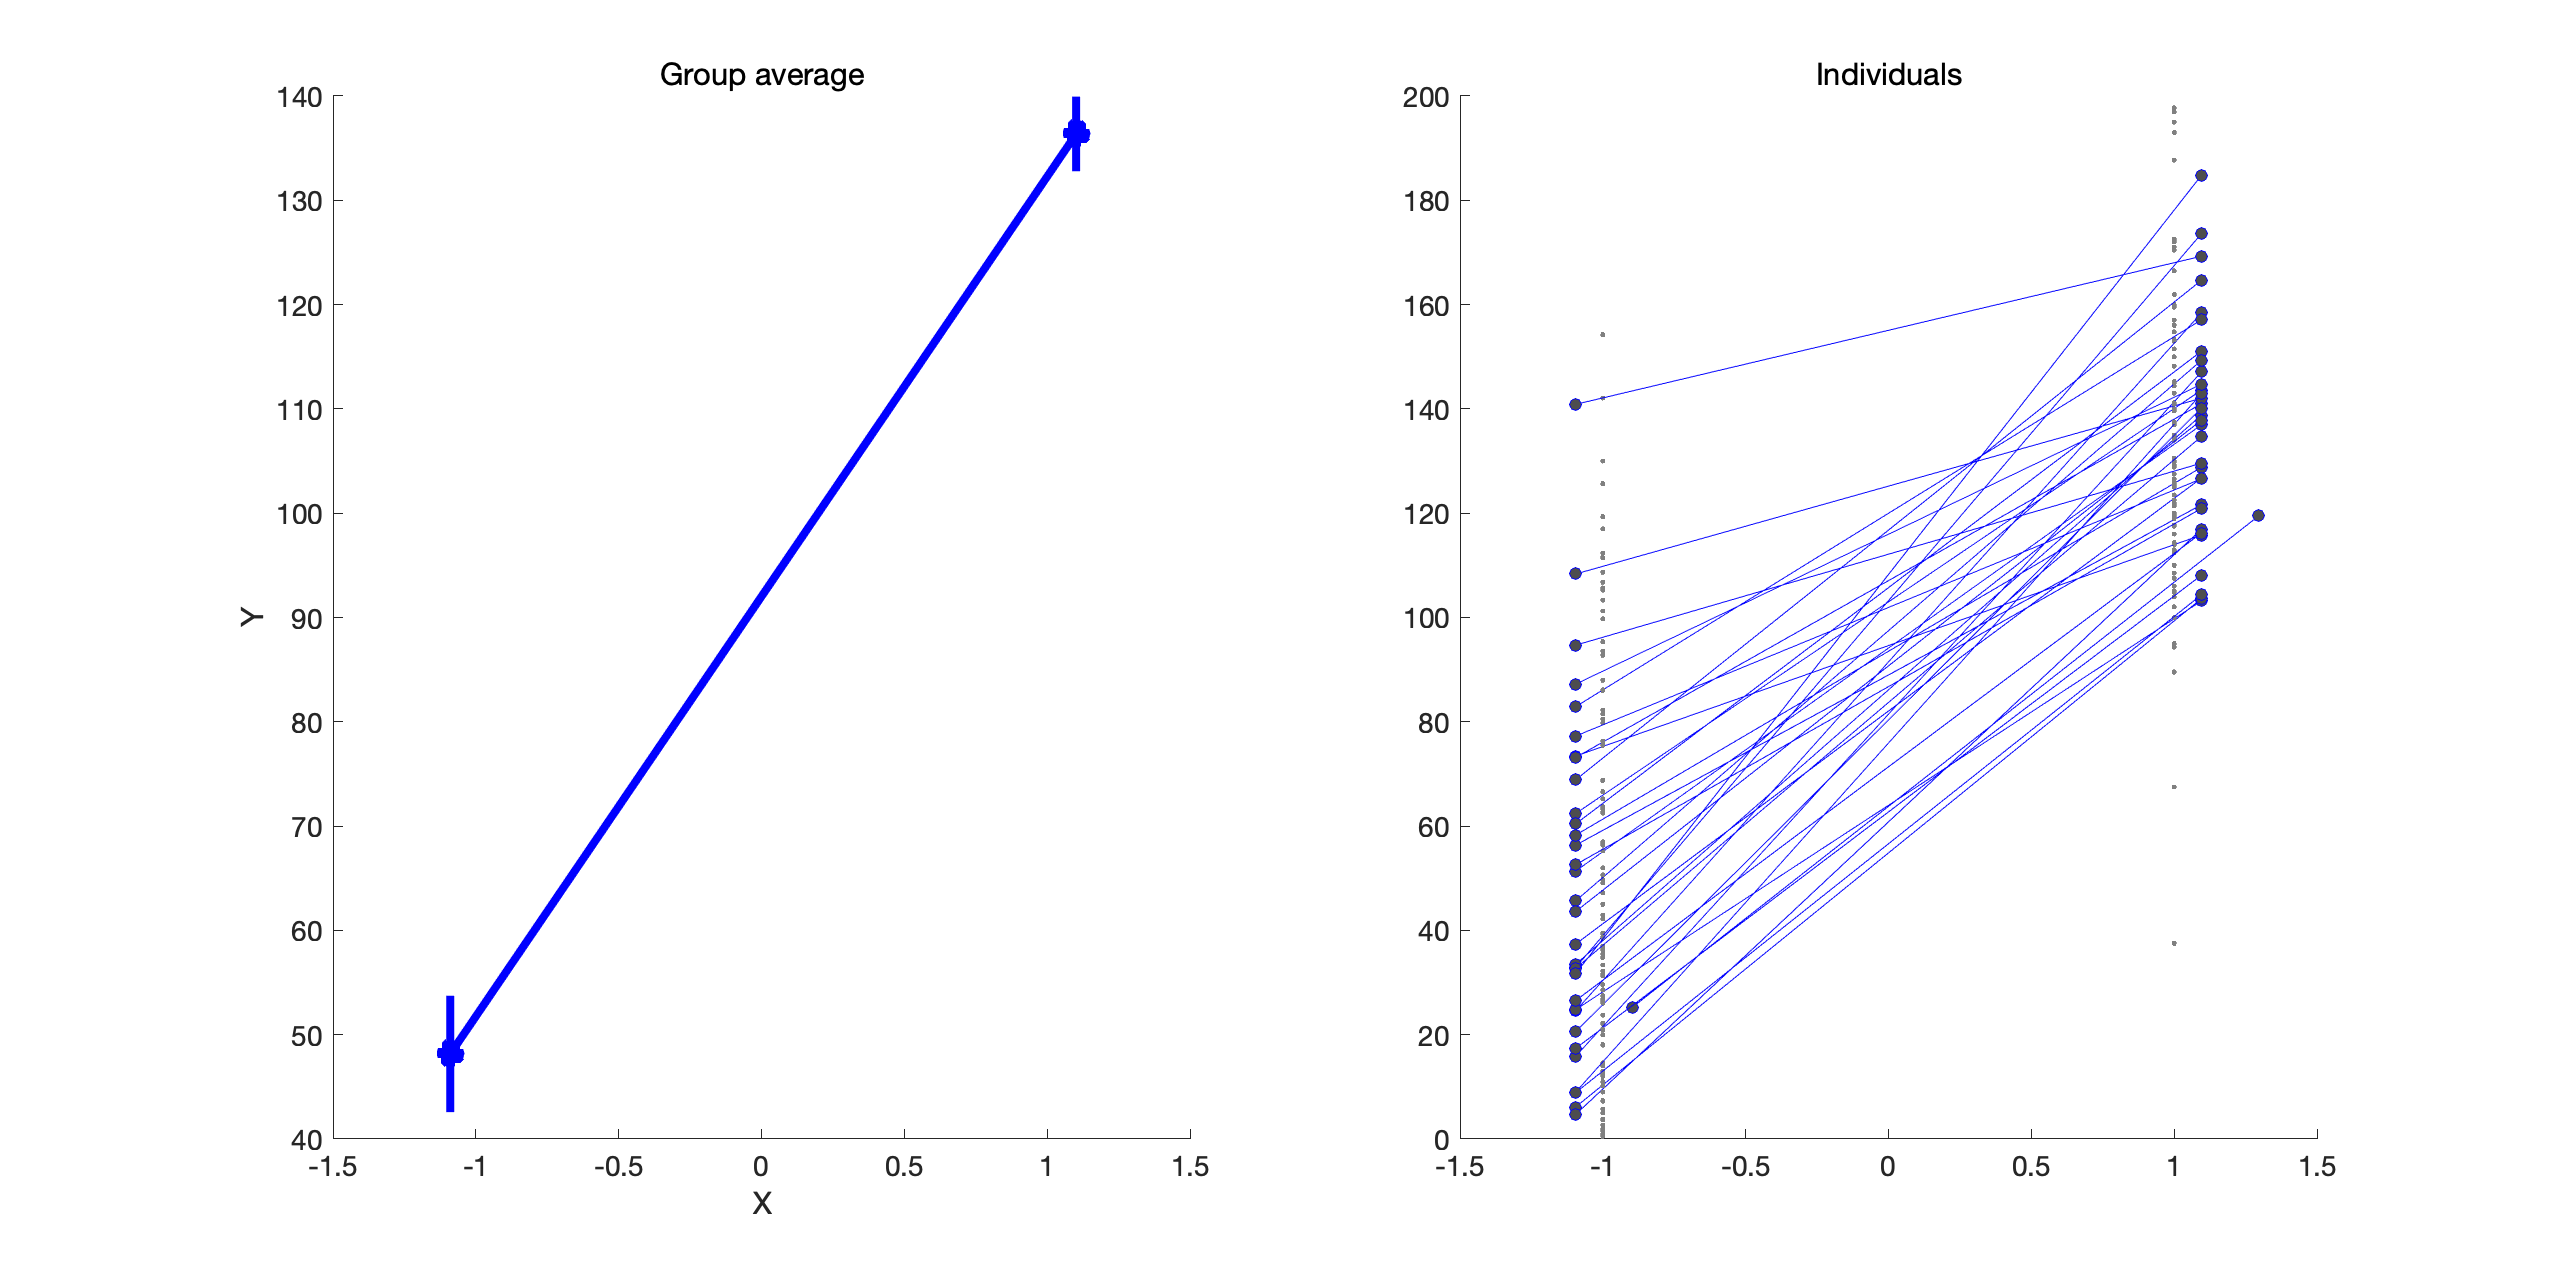

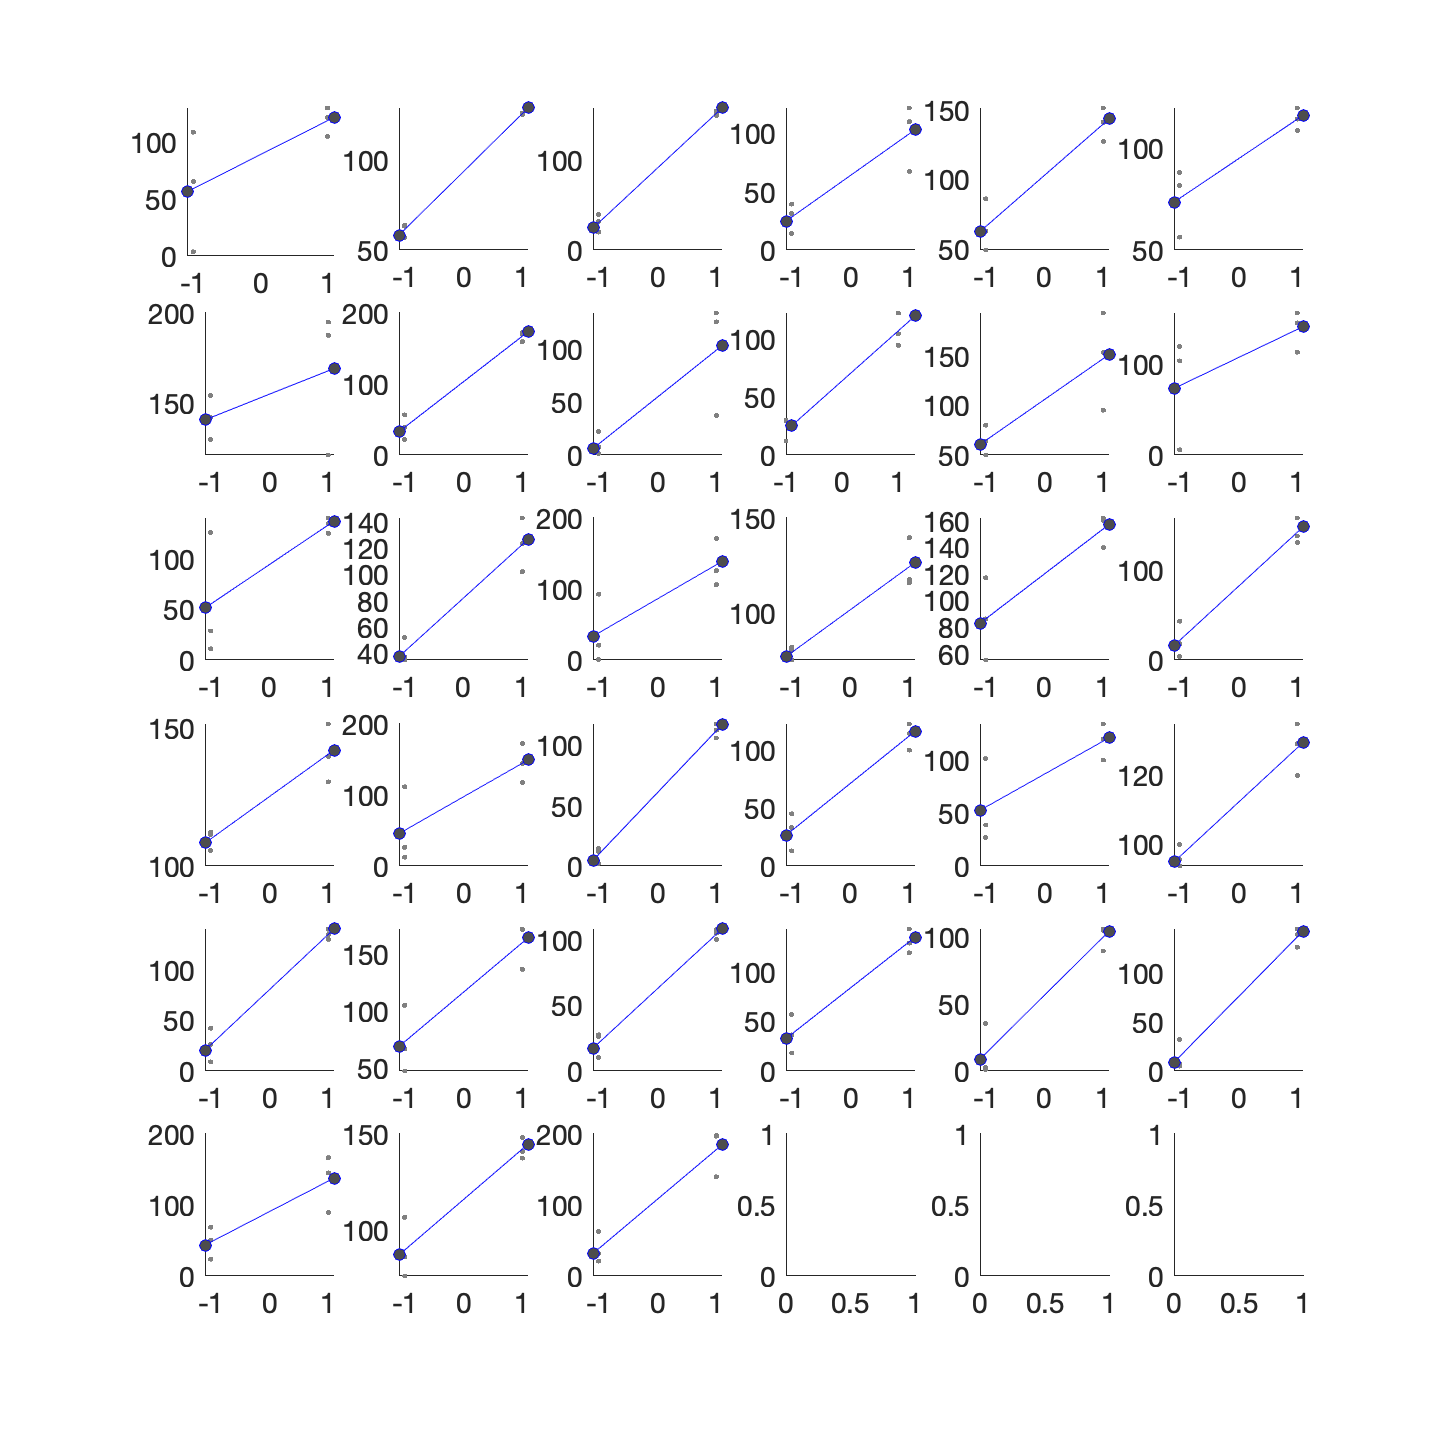

% with plot option
stats = glmfit_multilevel(y_rating, x, [], 'names', {'intercept', 'heat_level', 'regulation', 'interaction'}, 'plot');

% for nps
stats = glmfit_multilevel(y_nps, x, [], 'names', {'intercept', 'heat_level', 'regulation', 'interaction'});  

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  33, Predictors:   1
Outcome names: intercept	heat_level	regulation	interaction	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.00 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	intercept	heat_level	regulation	interaction	
Adj. mean	6.04	4.63	0.03	-0.05	

2nd-level B01
	intercept	heat_level	regulation	interaction	
Coeff	6.04	4.63	0.03	-0.05	
STE	0.69	0.53	0.39	0.39	
t	8.76	8.68	0.07	-0.13	
Z	6.21	6.18	0.07	-0.13	
p	0.00000	0.00000	0.94265	0.89838	

________________________________________


## Mediation analysis

x1: temperature

x2: regulation

m: nps

y: rating

for i = 1:33
    x1{i} = [1 1 1 2 2 2 3 3 3]'; % heat level
    x2{i} = [1 2 3 1 2 3 1 2 3]'; % cognitive regulation
    m{i} = nps(i,:)';
    y{i} = rating(i,:)';
end

[paths, stats] = mediation(x1, y, m, 'covs', x2, 'verbose');

Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: Yes,  33 columns

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: No
	Bootstrap: No
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No

Getting estimates for replications: 033 Done.

________________________________________

Multi-level model
	a	b	c'	c	ab	
Coeff	4.27	0.53	36.03	39.12	1.59	
STE	0.50	0.39	3.05	2.53	1.47	
t (~N)	8.63	1.36	11.82	15.43	1.08	
Z	6.13	1.32	7.07	8.21	1.05	
dfe	31.35	25.93	28.63	31.44	23.26	
p	0.0000	0.1852	0.0000	0.0000	0.2915	

________________________________________
Total time:   0 s


[paths, stats] = mediation(x2, y, m, 'covs', x1, 'verbose');

Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: Yes,  33 columns

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: No
	Bootstrap: No
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No

Getting estimates for replications: 033 Done.

________________________________________

Multi-level model
	a	b	c'	c	ab	
Coeff	-0.03	0.52	12.38	12.10	-0.11	
STE	0.39	0.39	2.84	2.72	0.50	
t (~N)	-0.08	1.34	4.36	4.46	-0.21	
Z	-0.08	1.30	3.83	3.89	-0.21	
dfe	30.53	26.18	31.34	31.53	25.19	
p	0.9376	0.1928	0.0001	0.0001	0.8340	

________________________________________
Total time:   0 s


[paths, stats] = mediation(x1, y, m, 'verbose', 'bootsamples', 10000);

Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: No
	Bootstrap: No
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No

Getting estimates for replications: 033 Done.

________________________________________

Multi-level model
	a	b	c'	c	ab	
Coeff	4.32	0.63	35.13	39.07	2.00	
STE	0.50	0.39	3.15	2.67	1.50	
t (~N)	8.60	1.61	11.16	14.61	1.33	
Z	6.12	1.56	6.90	7.92	1.30	
dfe	31.40	25.84	29.00	30.60	24.66	
p	0.0000	0.1196	0.0000	0.0000	0.1948	

________________________________________
Total time:   0 s


Mediation analysis

Observations:   1, Replications:  33
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: Yes
	Bootstrap: No
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No

Getting estimates for replications: 033 Done.
geom2d toolbox on your path.  I can't find it, so the path diagram will be skipped.


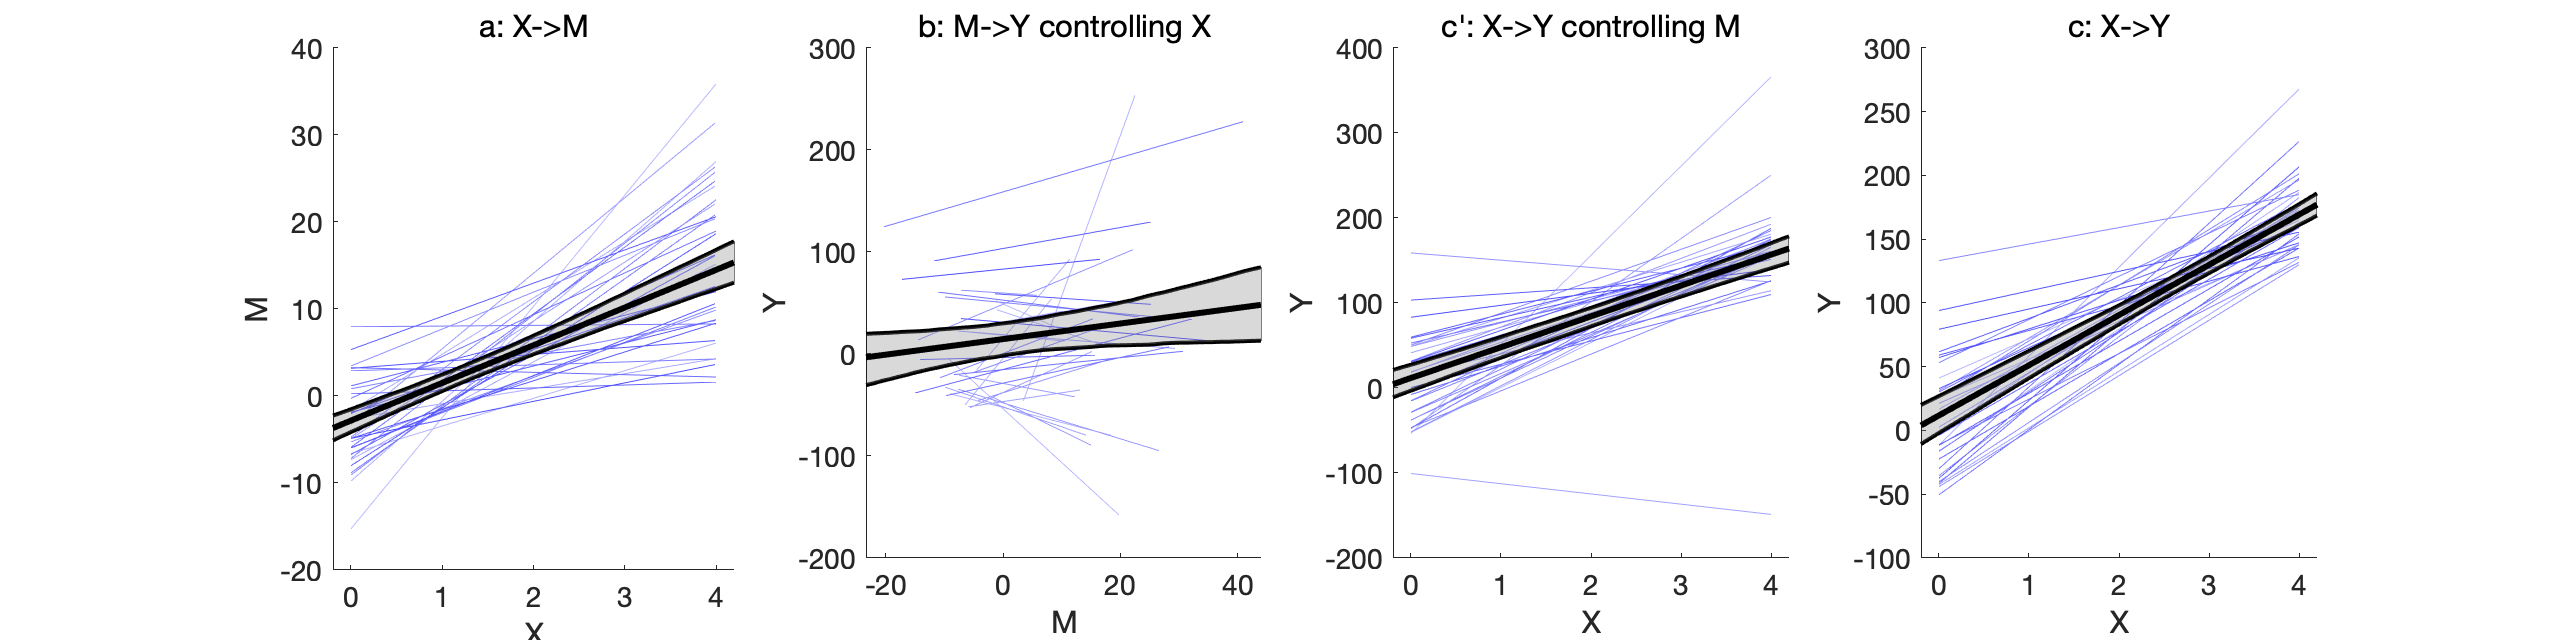

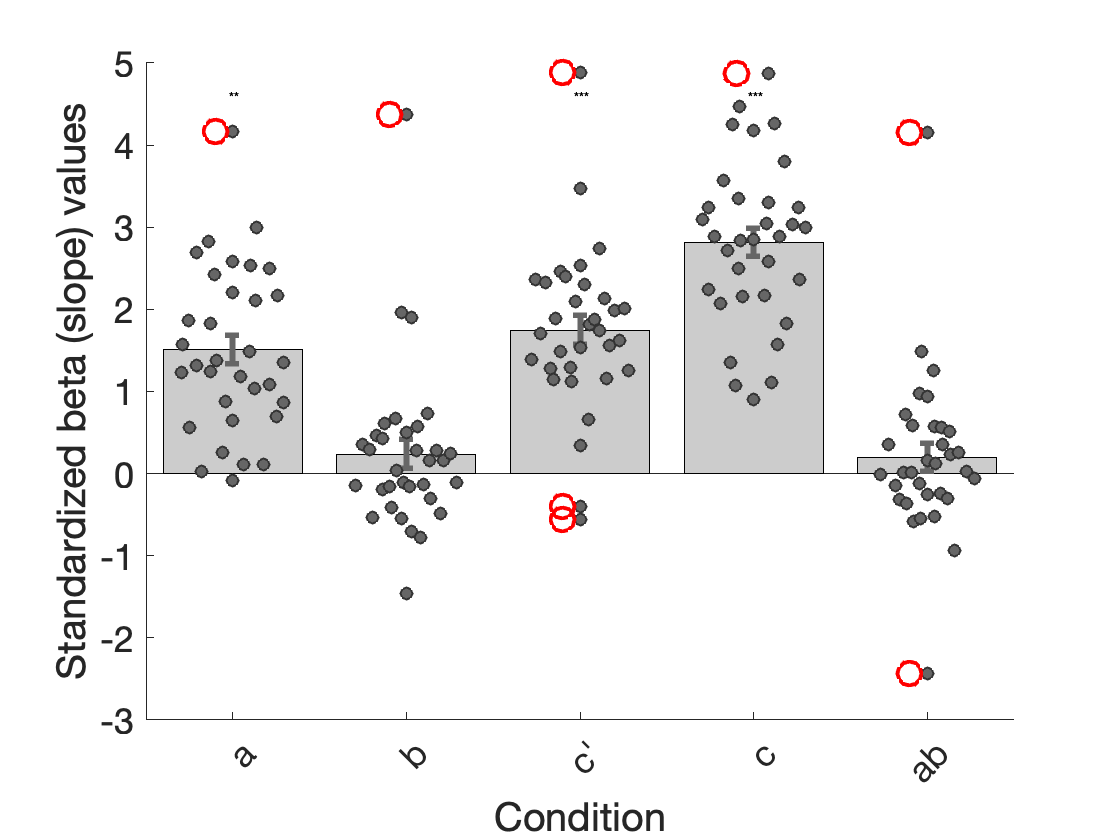

No second-level covariates; omitting 2nd level scatterplots.
Cannot find ebayes_bstar field in stats output, so cannot create cov(a,b) scatterplot

________________________________________

Multi-level model
	a	b	c'	c	ab	
Coeff	4.32	0.63	35.13	39.07	2.00	
STE	0.50	0.39	3.15	2.67	1.50	
t (~N)	8.60	1.61	11.16	14.61	1.33	
Z	6.12	1.56	6.90	7.92	1.30	
dfe	31.40	25.84	29.00	30.60	24.66	
p	0.0000	0.1196	0.0000	0.0000	0.1948	

________________________________________
Total time:   4 s


[paths, stats] = mediation(x1, y, m, 'verbose', 'plots','bootsamples', 10000);